Read the first image and its associated box label from the combined datastore.

I = gTruth.DataSource.Source(1);
bboxes = gTruth.LabelData(1,:);

imds = imageDatastore(gTruth.DataSource.Source);
blds = boxLabelDatastore(gTruth.LabelData(:,1:end));
trainingData = combine(imds,blds);


augmentedTrainingData = transform(trainingData,@jitterImageColorAndWarp);

Read all the augmented data.

data = readall(augmentedTrainingData);

The second augmentation rescales the image and box label to a target size. These operations are defined in the `resizeImageAndLabel` helper function at the end of this example.

targetSize = [480 640];
preprocessedTrainingData = transform(augmentedTrainingData,...
    @(data)resizeImageAndLabel(data,targetSize));

Read all of the preprocessed data.

data = readall(preprocessedTrainingData);

Display the augmented image and box label data.

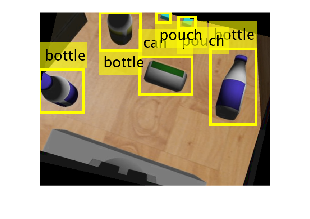

% Read the first image and its associated box label
I = data{8, 1};
bboxes = data{8, 2};
labels = data{8, 3};

% Ensure labels are in a cell array format
if iscategorical(labels)
    labels = cellstr(labels);
elseif ischar(labels)
    labels = {labels};
end

% Annotate the image
annotatedImage = insertObjectAnnotation(I, 'rectangle', bboxes, labels, ...
    'LineWidth', 8, 'FontSize', 40);

% Display the annotated image
imshow(annotatedImage);

% 从 data 变量中提取图像、边界框和标签数据
imdsAug = data(:, 1);
bboxes = data(:, 2);
labels = data(:, 3);

% 创建一个包含边界框和标签的数据表
tblAug = table(bboxes, labels);
% 创建 boxLabelDatastore
bldsAug = boxLabelDatastore(tblAug);

save imgs after augument

% 定义保存路径
savePath = 'E:\robocup2024\files\dataset\datasetAugument1';

% 确保保存路径存在，如果不存在则创建
if ~exist(savePath, 'dir')
    mkdir(savePath);
end

% 遍历imdsAug变量，保存每张图像
for i = 1:length(imdsAug)
    % 获取当前图像
    img = imdsAug{i};
    
    % 定义文件名（按顺序编号）
    fileName = sprintf('image_%04d.png', i);
    
    % 拼接完整文件路径
    fullPath = fullfile(savePath, fileName);
    
    % 保存图像为PNG格式
    imwrite(img, fullPath);
end

disp('图像保存完成。');

图像保存完成。


create a cell contained imgs path

% 定义图像文件夹路径
folderPath = savePath;

% 获取文件夹中的所有PNG文件
imageFiles = dir(fullfile(folderPath, '*.png'));

% 初始化变量
numImages = length(imageFiles);
imagePaths = cell(numImages, 1);

% 读取图像路径
for i = 1:numImages
    imagePaths{i} = fullfile(folderPath, imageFiles(i).name);
end



    {'E:\robocup2024\files\dataset\datasetAugument1\image_0001.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0002.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0003.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0004.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0005.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0006.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0007.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0008.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0009.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0010.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0011.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0012.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0013.png'}
    {'E:\robocup2024\files\dataset\datasetAugument1\image_0014.png'}
    {'E:\robocup2024\files\dataset

combine all dataset (gtruth and aaugument)

   % 从 gTruth.DataSource.Source 获取图像地址
gTruthPaths = gTruth.DataSource.Source;

% 从 imagePaths 获取图像地址
augmentedPaths = imagePaths;

% 获取总图像数量
totalNumImages = size(gTruthPaths, 1) + size(augmentedPaths, 1);

% 初始化新的变量来存储所有图像地址
allImagePaths = cell(totalNumImages, 1);

% 将 gTruthPaths 中的图像地址放入 allImagePaths
for i = 1:size(gTruthPaths, 1)
    allImagePaths{i} = gTruthPaths{i};
end

% 将 augmentedPaths 中的图像地址放入 allImagePaths
for i = 1:size(augmentedPaths, 1)
    allImagePaths{size(gTruthPaths, 1) + i} = augmentedPaths{i};
end

%allImagePaths is the images after augmentaion!

% 从 blds 和 bldsAug 中提取 LabelData
labelData1 = blds.LabelData;
labelData2 = bldsAug.LabelData;

% 获取每个数据集的大小
numLabelData1 = size(labelData1, 1);
numLabelData2 = size(labelData2, 1);

% 初始化一个新的变量来存储所有的标签数据
combinedLabelData = cell(numLabelData1 + numLabelData2, 2);

% 将 blds 的 LabelData 复制到 combinedLabelData
for i = 1:numLabelData1
    combinedLabelData{i, 1} = labelData1{i, 1};
    combinedLabelData{i, 2} = labelData1{i, 2};
end

% 将 bldsAug 的 LabelData 复制到 combinedLabelData
for i = 1:numLabelData2
    combinedLabelData{numLabelData1 + i, 1} = labelData2{i, 1};
    combinedLabelData{numLabelData1 + i, 2} = labelData2{i, 2};
end

% 创建一个新的 boxLabelDatastore
combinedTable = cell2table(combinedLabelData, 'VariableNames', {'bboxes', 'labels'});
combinedBlds = boxLabelDatastore(combinedTable);
%combinedBlds is blds after augmentation!


Final Step create new ds after augument

imdsAfterAugment = imageDatastore(allImagePaths);
bldsAfterAugment = combinedBlds;
dsAfterAugument = combine(imdsAfterAugment,bldsAfterAugment);
%dsAfterAugument is the final dataset after augmentation

Other Functions

function out = jitterImageColorAndWarp(data)
% Unpack original data.
I = data{1};
boxes = data{2};
labels = data{3};

% Apply random color jitter.
I = jitterColorHSV(I,"Brightness",0.3,"Contrast",0.4,"Saturation",0.2);

% Define random affine transform.
tform = randomAffine2d("XReflection",true,'Rotation',[-30 30]);
rout = affineOutputView(size(I),tform);

% Transform image and bounding box labels.
augmentedImage = imwarp(I,tform,"OutputView",rout);
[augmentedBoxes, valid] = bboxwarp(boxes,tform,rout,'OverlapThreshold',0.4);
augmentedLabels = labels(valid);

% Return augmented data.
out = {augmentedImage,augmentedBoxes,augmentedLabels};
end

The `resizeImageAndLabel` helper function calculates the scale factor for the image to match a target size, then resizes the image using `imresize` and the box label using `bboxresize`. The input and output data are two-element cell arrays, where the first element is the image data and the second element is the box label data.

function data = resizeImageAndLabel(data,targetSize)
scale = targetSize./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize);
data{2} = bboxresize(data{2},scale);
end